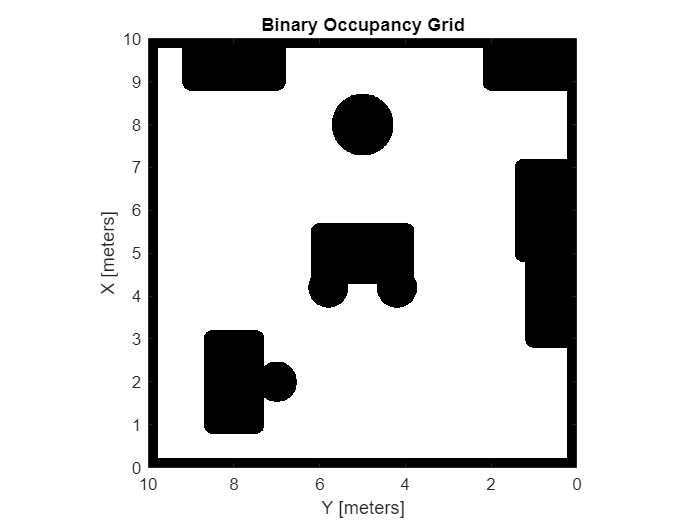

colobj = roomspec();

resolution = 100;
binary_map = colobj2binary_map(colobj, resolution);

inflate(binary_map, 0.2)

show(binary_map);
view(-90,90);



% hold on
% roomshow(roomspec)
% hold off

function plot_scans(ranges, angles, pose)
hold on

for i = 1:length(ranges)
    plot(pose(1)+[0 cos(pose(3)+angles(i))*ranges(i)], pose(2)+[0 sin(pose(3)+angles(i))*ranges(i)], 'k')
    
end

hold off
end